# Design of a nonlinear filter bank

***Our filter will focus on frequencies which are of importance in the power spectrum of our IR***

**Configurate the path and clear the workspace, etc.**

clc; close all; clear;
addpath(genpath(fullfile('../')));

## Inspect (Welch-Linear) IR samples for each direction: Front, Left, Back, Right

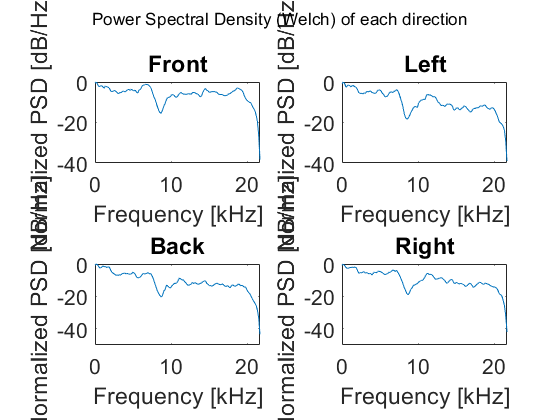

nameIRms = "IR44K_2s_1000ms";

fs = 44100;
IRLen = 40;
dir = "aux_data/IR_Z_fixed/2s/"; % Azimuth
IRms = struct2cell(load(dir+nameIRms));
IRms = IRms{1};
IRms =IRms(:,2);
IRms = [IRms{:}];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
% PSD Welch Method parameters
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
segmentLength = 256;            % Segments will be 512 samples (goes to 257 when taking positive frequencies only)
noverlap = segmentLength/2;     % 50 percent overlap
win = hamming(segmentLength);             % sample-length hanning window
N_bins = (segmentLength/2)+1;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
df = fs/(2*((segmentLength/2)+1));
f = 0:df:(fs-df)/2;

noise = randn(fs,1);
noise_aug = zeros(fs,4);
noise_psd = zeros(N_bins,4);
for i = 1:4
    irIdx = 1 + (i-1)*10;
    noise_aug(:,i) = conv(noise, IRms(:,irIdx),"same");
    noise_windowed_fft  = welch_window(noise_aug(:,i),segmentLength,noverlap, win); % Perform windowing with 50% overlap and apply fft
    
    Pxx = welch_input_fft(noise_windowed_fft, win, fs); % Calculate periodograms and average
    Pxx = normalize(Pxx,'range');
    noise_psd(:,i) = Pxx;
end

figure;
titles = ["Front", "Left", "Back", "Right"];
for i = 1:4
    subplot(2,2,i); plot(f/1000,10*log10(noise_psd(:,i))); xlabel("Frequency [kHz]"); ylabel("Normalized PSD [dB/Hz]"); title(titles(i));
    ax = gca;
    ax.FontSize = 16;
end

sgtitle("Power Spectral Density (Welch) of each direction");

## Use of Linear Prediction to estimate resonance frequencies

resonances = cell(4,4);

nfft = 512;
order = 12;

for i = 1:4
    irIdx = 1 + (i-1)*10;
    [IR_cut, IR_psd,fre, notch_frequencies, notch_bandwidths, ...
    notch_magnitudes, p] = spectral_null_extraction(IRms(:,irIdx),fs,order, nfft);
    resonances{i,1} =notch_frequencies;
    resonances{i,2} =notch_magnitudes;
    resonances{i,3} =notch_bandwidths;
    resonances{i,4} = p;
    
end

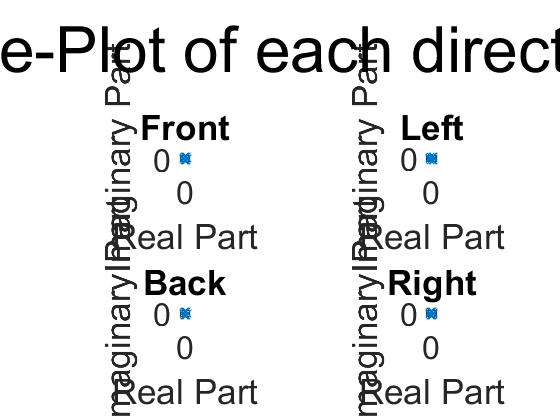

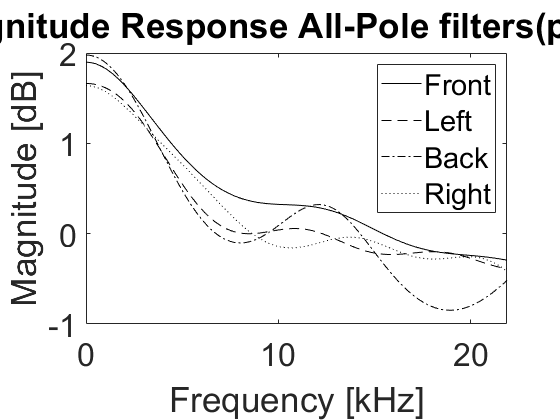

figure;
titles = ["Front", "Left", "Back", "Right"];
for i = 1:4
    subplot(2,2,i); zplane([],resonances{i,4}); title(titles(i),"FontSize",32);
    ax = gca;
    ax.FontSize = 24;
end
sgtitle("Pole-Plot of each direction", "FontSize",48);

## Filter design

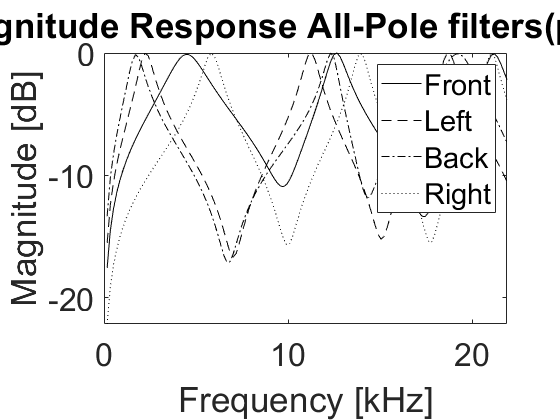

peak_filters = cell(4,1);
for i = 1:4
    freqs = resonances{i,1};
    bws = resonances{i,3};
    l = length(freqs);
    h = cell(l,1);
    for p = 1:l
        filt = fdesign.peak('N,F0,BW,Ap,Ast', 2,freqs(p),bws(p)/5,0.01,80, fs);
        h{p} = design(filt);
    end
    hd = dfilt.parallel(h{:});
    peak_filters{i} = hd;
end
figure;
line = ["-", "--", "-.", ":"];
for i = 1:4
    h = freqz(peak_filters{i},segmentLength);
    h = abs(h(1:(segmentLength/2)+1));
    h = normalize(h, 'range');
    plot(f/1000,10*log10(abs(h)),'k',"LineStyle",line(i)); hold on;
end
ax = gca;
ax.FontSize = 24;
xlabel("Frequency [kHz]"); ylabel("Magnitude [dB]"); title("Magnitude Response All-Pole filters(p = " +order+")", "FontSize",48);
legend("Front","Left", "Back", "Right");

***Select the correct filters: ***

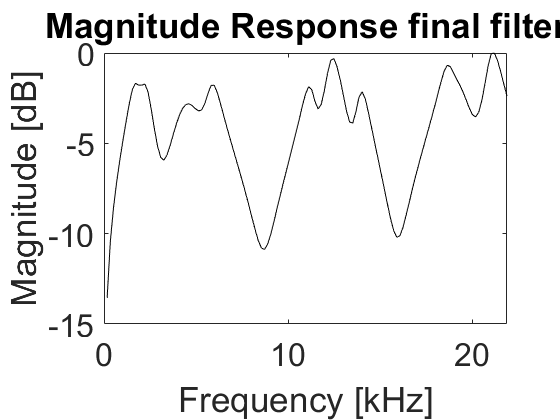

figure;
final_filter = dfilt.parallel(peak_filters{:});
h = freqz(final_filter,segmentLength);
h = abs(h(1:(segmentLength/2)+1));
h = normalize(h,'range');
plot(f/1000,10*log10(abs(h)),'k');
xlabel("Frequency [kHz]"); ylabel("Magnitude [dB]"); title("Magnitude Response final filter","FontSize",48);
ax = gca;
ax.FontSize = 24;

## PSD of filtered noise

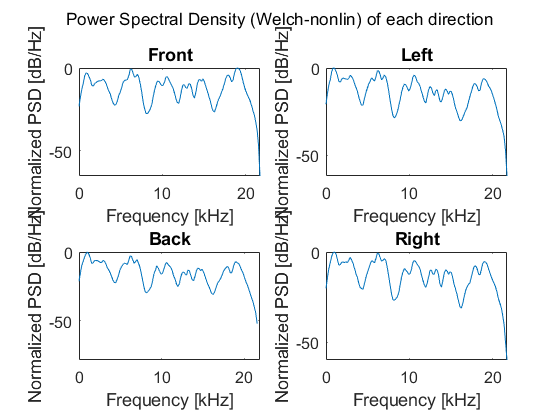

noise_filtered = zeros(N_bins,4);
for i = 1:4
    n = filter(final_filter,noise_aug(:,i)); 
    noise_windowed_fft  = welch_window(n,segmentLength,noverlap, win); % Perform windowing with 50% overlap and apply fft
    Pxx = welch_input_fft(noise_windowed_fft, win, fs); % Calculate periodograms and average
    Pxx = normalize(Pxx,'range');
    noise_filtered(:,i) = Pxx;
end


figure;
titles = ["Front", "Left", "Back", "Right"];

for i = 1:4
    subplot(2,2,i); plot(f/1000,10*log10(noise_filtered(:,i))); xlabel("Frequency [kHz]"); ylabel("Normalized PSD [dB/Hz]"); title(titles(i));
    hold on;
    ax = gca;
    ax.FontSize = 12;
end
sgtitle("Power Spectral Density (Welch-nonlin) of each direction");

See if the overlap is alright

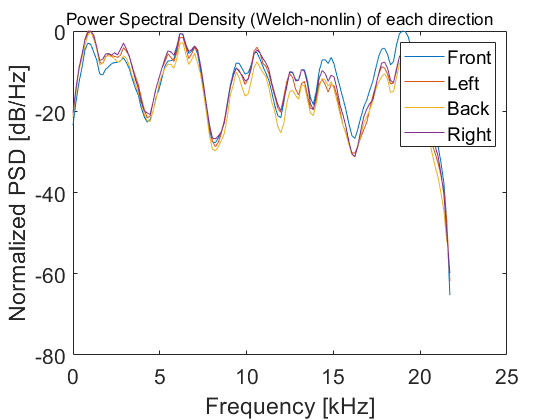

figure;
titles = ["Front", "Left", "Back", "Right"];
for i = 1:4
    plot(f/1000,10*log10(noise_filtered(:,i))); xlabel("Frequency [kHz]"); ylabel("Normalized PSD [dB/Hz]");
    hold on;
    ax = gca;
    ax.FontSize = 16;
end
legend("Front", "Left", "Back", "Right");
sgtitle("Power Spectral Density (Welch-nonlin) of each direction");

## Save filter as object

save("../filter","final_filter");